# Numerical Differentiation and Numerical Integration

clear, close all

## Numerical Differentiation Given Data

Suppose $f(x)$ is only known at a discrete set of points $a = x_1 < x_2 < \cdots < x_n = b$. Approximate $f'(x)$ at the given nodes. 

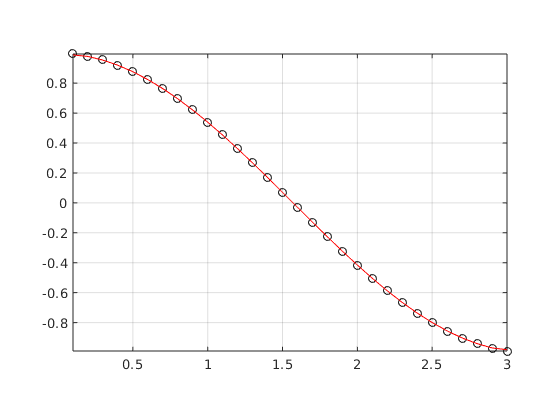

% artificially made data for demo
x = 0.1:0.1:3;
fx = sin(x);

n = length(x);
dfdx = zeros(size(fx));
h = x(2) - x(1);
dfdx(1) = (fx(2)-fx(1))/h;              % forward difference (1st-order)
dfdx(2:end-1) = ...
    (fx(3:end)-fx(1:end-2))/(2*h);      % centered difference (2nd-order)
dfdx(end) = (fx(end)-fx(end-1))/h;      % backward difference (1st-order)

figure(1)
plot(x, cos(x), 'ko')  % exact
hold on
plot(x, dfdx, 'r')     % numerical
axis image
grid on

### Exercise

Modify the previous script to use the 2nd-order FD and BD formulas at the end points.

## Optimal Value of $h$ for Numerical Differentiation

Consider $f(x) = \sin(x^2)$ whose derivative is easily calculated: 


$$f'(x) = 2x \cos(x^2)$$


Let's code in various finite difference formulas as anonymous functions:

f = @(x) sin(x.^2);
fprime = @(x) 2*x.*cos(x.^2);
Df1f = @(x,h) (f(x+h) - f(x))./h;
Df2f = @(x,h) (-3*f(x) + 4*f(x+h) - f(x+2*h))./(2*h);
Df2c = @(x,h) (f(x+h) - f(x-h))./(2*h);
Df4c = @(x,h) (f(x-2*h) - 8*f(x-h) + 8*f(x+h) - f(x+2*h))./(12*h);

Note the 4-th order centered difference formula, which was not derived in class. 

We will numerically calculate $f'(1/3)$ using these formulas with various $h$ values and tabulate the errors.

x = 1/3;
h0 = 0.1;
nr_h = 35;
h = h0*2.^(-[0:nr_h]');           % h halved successively
Err1f = Df1f(x,h) - fprime(x);
Err2f = Df2f(x,h) - fprime(x);
Err2c = Df2c(x,h) - fprime(x);
Err4c = Df4c(x,h) - fprime(x);
table(h, Err1f, Err2f, Err2c, Err4c)

ans = 36×5 table
        h           Err1f         Err2f          Err2c          Err4c   
    __________    __________    __________    ___________    ___________
    1.0000e-01    9.5380e-02    4.6076e-03    -1.2624e-03     1.2913e-04
    5.0000e-02    4.8116e-02    8.5127e-04    -3.0953e-04     8.1062e-06
    2.5000e-02    2.4149e-02    1.8138e-04    -7.7002e-05     5.0718e-07
    1.2500e-02    1.2095e-02    4.1777e-05    -1.9227e-05     3.1707e-08
    6.2500e-03    6.0526e-03    1.0020e-05    -4.8052e-06     1.9818e-09
    3.1250e-03    3.0275e-03    2.4532e-06    -1.2012e-06     1.2386e-10
    1.5625e-03    1.5141e-03    6.0692e-07    -3.0029e-07     7.7557e-12
    7.8125e-04    7.5711e-04    1.5094e-07    -7.5073e-08     4.8594e-13
    3.9063e-04    3.7857e-04    3.7635e-08    -1.8768e-08    -2.7645e-14
    1.9531

The log-log graphs of errors displays the accuracy of the methods. 

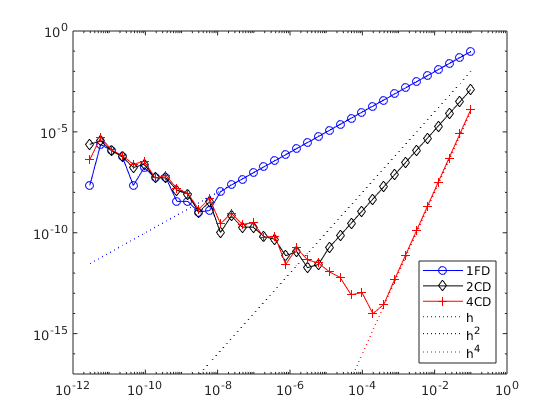

clf
loglog(h, abs(Err1f), 'bo-')
hold on
loglog(h, abs(Err2c), 'kd-')
loglog(h, abs(Err4c), 'r+-')
loglog(h, h, 'b:')
loglog(h, h.^2, 'k:')
loglog(h, h.^4, 'r:')
legend('1FD', '2CD', '4CD', 'h', 'h^2', 'h^4',...
    'Location', 'Southeast')
ylim([1e-17, 1])

## Composite Trapezoidal Method

Let $f(x) = \sin^2 x$. Here we calculate numerically


$$I\{f\} = \int_0^1 f(x) \; dx$$


using composite trapezoidal rule with the equispaced grid points $0 = x_1 < x_2 < \cdots < x_n = 1$:


$$I^{\rm [t]}_h \{f\} = \frac{h}{2} (f(x_1) + f(x_n)) + h \sum_{j=2}^{n-1} f(x_j).$$


Since the exact integral $I\{f\}$ can be calculated exactly, we are able to calculate the errors $I - I^{\rm [t]}_h$ for varying $h$ values and monitor how the error changes. 

n = 10;          % number of intervals
nr_exp = 15;     % number of experiments
a = 0; b = 1;
f = @(x) sin(x).^2;
f_int = @(x) x/2 - sin(2*x)/4;
exact_area = f_int(b) - f_int(a);
M = zeros(nr_exp, 2);
for i = 1:nr_exp
    x = linspace(a, b, n+1);
    h = x(2) - x(1);
    c = ones(size(x));
    c([1,end]) = .5;
    area = h*c*f(x');     % <--- comp. trap. method
    M(i,1) = h;
    M(i,2) = area - exact_area;
    n = 2*n;
end
fprintf(' %12s %12s \n', 'h', 'error')

            h        error 


fprintf(' %25s \n', repmat('-', 1, 25))

 ------------------------- 


for i = 1:nr_exp
    fprintf(' %12.4g %12.4e \n', M(i,:))
end

          0.1   7.5825e-04 
         0.05   1.8947e-04 
        0.025   4.7361e-05 
       0.0125   1.1840e-05 
      0.00625   2.9600e-06 
     0.003125   7.3999e-07 
     0.001563   1.8500e-07 
    0.0007813   4.6249e-08 
    0.0003906   1.1562e-08 
    0.0001953   2.8906e-09 
    9.766e-05   7.2264e-10 
    4.883e-05   1.8066e-10 
    2.441e-05   4.5165e-11 
    1.221e-05   1.1291e-11 
    6.104e-06   2.8229e-12 


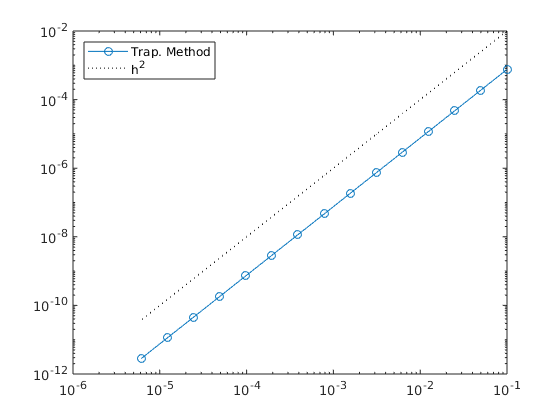

hh = M(:, 1);
figure()
loglog(hh, abs(M(:, 2)), 'o-');
hold on
loglog(hh, hh.^2, 'k:')
legend('Trap. Method', 'h^2', 'Location', 'Northwest')

### Exercise

Modify the script above to verify that the composite Simpson's rule is indeed 4-th order accurate.

n = 10;          % number of intervals
nr_exp = 8;     % number of experiments
a = 0; b = 1;
f = @(x) sin(x).^2;
f_int = @(x) x/2 - sin(2*x)/4;
exact_area = f_int(b) - f_int(a);
M = zeros(nr_exp, 2);
for i = 1:nr_exp
    x = linspace(a, b, n+1);
    xl = x(1:end-1);
    xr = x(2:end);
    xm = (xl + xr)/2;
    h = x(2) - x(1);
    c = h/6*[1 4 1];
    area = c*[sum(f(xl)); sum(f(xm)); sum(f(xr))]; % <--- comp. Simpson
    M(i,1) = h;
    M(i,2) = area - exact_area;
    n = 2*n;
end
fprintf(' %12s %12s \n', 'h', 'error')
fprintf(' %25s \n', repmat('-', 1, 25))
for i = 1:nr_exp
    fprintf(' %12.4g %12.4e \n', M(i,:))
end
hh = M(:, 1);
figure()
loglog(hh, abs(M(:, 2)), 'o-');
hold on
loglog(hh, hh.^4, 'k:')
legend('Simpson', 'h^4', 'Location', 'Northwest')

## Euler Spiral and Simpson's Method

Consider the following parametrized curve:


$$x(t)  = \int_0^t \cos( z^2 ) \; dz$$



$$y(t) = \int_0^t \sin( z^2 ) \; dz$$


which is called an *Euler sprial* or a *clothoid*. This is known to have a curvature that is linearly proportional to arc length. 

We will plot this curve for $t \in [0, T]$ with $T = 15$. To this end, we need to evaluate $x(t)$ and $y(t)$ at discrete points $t_k = k h$ where $0 \le k \le T/h$ and $h$ is chosen so that $T/h$ is an integer; call it $N$. 

Define, for $1 \le j \le N$, 

$\displaystyle I_{x, j} = \int_{t_{j-1}}^{t_j} \cos( z^2 ) \; dz$   and   $\displaystyle I_{y, j} = \int_{t_{j-1}}^{t_j} \sin( z^2 ) \; dz$.

Then we note that


$$x_k = x(t_k) = \int_0^{t_k} \cos( z^2 ) \; dz  = \sum_{j=1}^k I_{x, j},$$


and


$$y_k = y(t_k) = \int_0^{t_k} \sin( z^2 ) \; dz = \sum_{j=1}^k I_{y, j}.$$


So our computation boils down to calculating integrals $I_{x, j}$ and $I_{y, j}$. We will calculate them using Simpson's method (non-composite):


$$I^{\rm [s]} \{f\} = \frac{h}{6} \left( f(a) + 4 f(m) + f(b) \right).$$


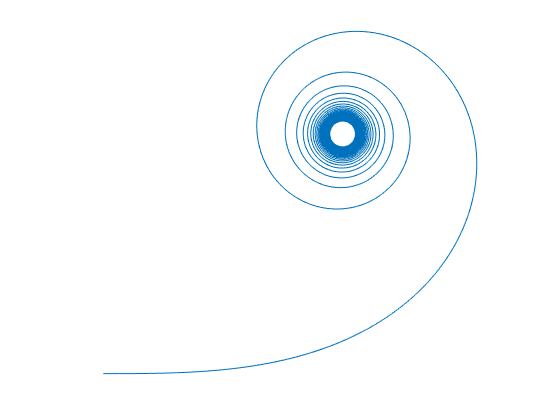

T = 15;
h = 0.001;
t = (0:h:T);
tmid = ( t(1:end-1)+t(2:end) )/2;
fx = @(z) cos(z.^2);
fy = @(z) sin(z.^2);
Ix = h/6 * ( fx(t(1:end-1)) + 4*fx(tmid) + fx(t(2:end)) );
Iy = h/6 * ( fy(t(1:end-1)) + 4*fy(tmid) + fy(t(2:end)) );
x = cumsum(Ix);
y = cumsum(Iy);

figure()
plot(x, y)
axis equal, axis off
grid on